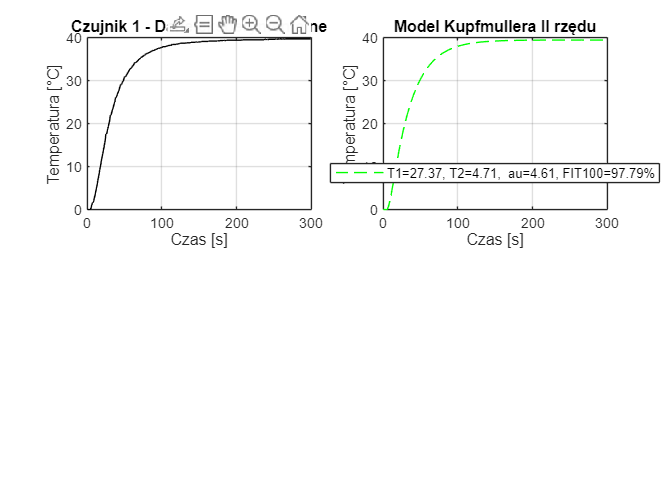


Czujnik 1:


k = 39.4393, T1 = 27.3659, T2 = 4.7081, tau = 4.6118


MSE = 14.1371, FIT100 = 97.79%


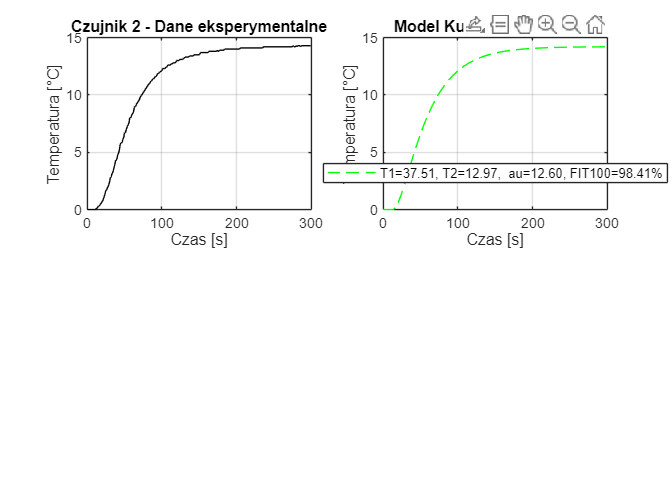


Czujnik 2:


k = 14.2051, T1 = 37.5076, T2 = 12.9696, tau = 12.6006


MSE = 1.5358, FIT100 = 98.41%


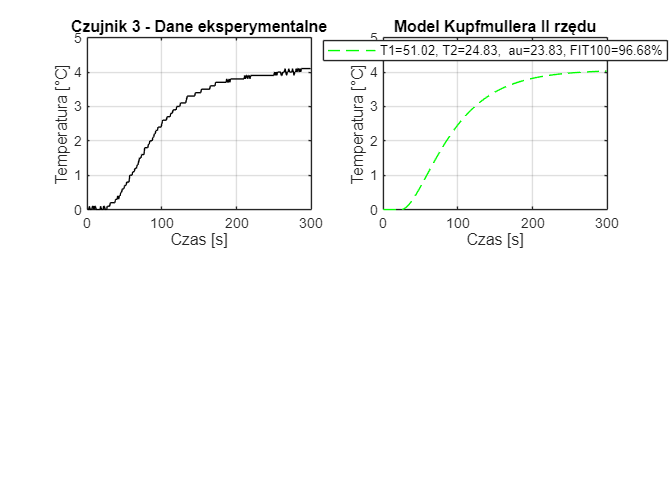


Czujnik 3:


k = 4.0631, T1 = 51.0234, T2 = 24.8262, tau = 23.8344


MSE = 0.7099, FIT100 = 96.68%


% ------------------------------
% Model Kupfmullera II rzędu z opóźnieniem
% ------------------------------

clear; clc; close all;
load piecyk_3_cels.mat
czas = 0:1:299;
u = ones(length(czas), 1);
kolory = ['r', 'g', 'b'];
nazwy = {'Czujnik 1', 'Czujnik 2', 'Czujnik 3'};

for i = 1:3
    % Dane i normalizacja
    y = piecyk_3_cels(:, i);
    y = y - y(1);
    k_static = y(end);

    % Estymacja parametrów: [k, T1, T2, tau]
    [param, mse] = fminsearch(@(X) ident_Kupf2(X, y, czas), [k_static, 20, 20, 10]);
    K = param(1); T1 = param(2); T2 = param(3); tau = param(4);

    % Model i odpowiedź skokowa
    model = tf(K, [T1*T2, T1+T2, 1], 'OutputDelay', tau);
    ym = step(model, czas);

    % Porównanie z danymi – FIT100
    Ye = iddata(y, u, 1);
    model_id = idtf(model);
    [~, fit, ~] = compare(Ye, model_id);

    % Wykresy
    figure;
    subplot(2,2,1);
    plot(czas, y, 'k');
    title([nazwy{i} ' - Dane eksperymentalne']); grid on;
    xlabel('Czas [s]'); ylabel('Temperatura [°C]');

    subplot(2,2,2);
    plot(czas, ym, 'g--');
    legenda = sprintf('T1=%.2f, T2=%.2f, \tau=%.2f, FIT100=%.2f%%', T1, T2, tau, fit);
    title('Model Kupfmullera II rzędu');
    legend(legenda, 'Location', 'best'); grid on;
    xlabel('Czas [s]'); ylabel('Temperatura [°C]');

    fprintf("\nCzujnik %d:\n", i);
    fprintf("k = %.4f, T1 = %.4f, T2 = %.4f, tau = %.4f\n", K, T1, T2, tau);
    fprintf("MSE = %.4f, FIT100 = %.2f%%\n", mse, fit);
end


% ------------------------------
function blad = ident_Kupf2(X, y, t)
    K = X(1); T1 = X(2); T2 = X(3); tau = X(4);
    if K < 0 || T1 <= 0 || T2 <= 0 || tau < 0
        blad = inf; return;
    end
    model = tf(K, [T1*T2, T1+T2, 1], 'OutputDelay', tau);
    ym = step(model, t);
    blad = sum((y(:) - ym(:)).^2);
end
